# Physical/Electrical Modeling of Transmission

Electrical    Physical 

v [Volts]      p [N/m^2] 

i [Amps]      dm [kg/s]

N = kg m/s^2

## Capacitance

 i = C dv/dt 

syms kg s C N m
N = kg*m/s^2;
f = kg/s - C*N/(m^2*s);
C_units = solve(f,C)

$$C\_units = m\,s^{2}$$

## Inductance

v = L di/dt

syms kg s L N m
N = kg*m/s^2;
f = N/m^2 - L*kg/s^2;
L_units = solve(f,L)

$$L\_units = \frac{1}{m}$$

## U-Tube and RLC circuit

For a Manometer

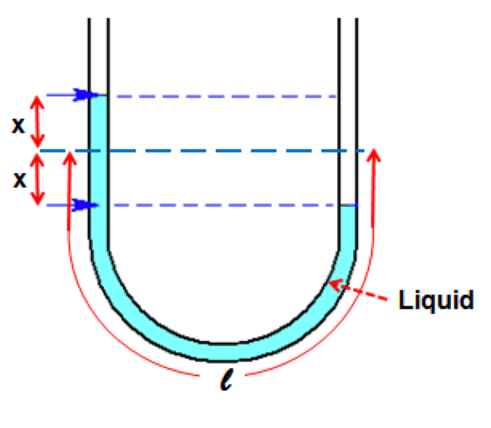 

Total pressure is $2 \rho g x$

That pressure acts on a mass of water $\rho l A$


$$-2 \rho g x A = \rho l A \; d^2x/dt$$



$$-2 g x = l \; d^2x/dt$$



$$\omega_0 = \sqrt{2 g / l}$$


Where x is the displacement of the water level from equilibrium

for a pi circuit,

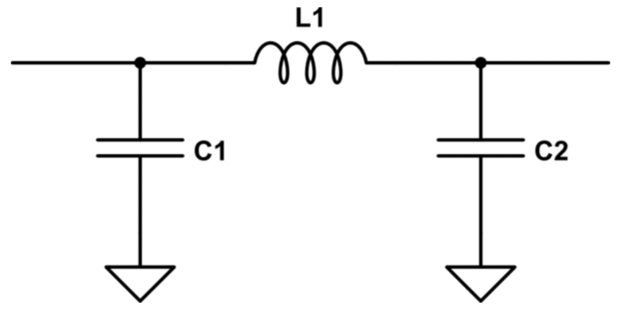


$$L \; di/dt + 1/C \int i \; dt = -1/C \int i \; dt$$



$$L \; \frac{d^2i}{dt^2} + 2/C i = 0$$



$$\omega_0 = \sqrt{2/(LC)}$$


Looking at the manometer equation again


$$-2 \rho g v A = \rho l A \; d^2v/dt$$



$$-2 g \dot{m} = l \; d^2 \dot{m}/dt$$



$$-2 g/l^2 \dot{m} = 1/l \; d^2 \dot{m}/dt$$



$$L = 1/l$$



$$C = l^2/g$$


## Derivation From 2 Columns with Tunnel

x (l) is toward shore, y (w) is along shore, and z (h) is depth.

Assume two columns with a tunnel.  The tunnel penetrates half way into each column.

Assume the pressure acts at h/2.  Assume the variation in water surface elevation is small compared to h.

Tunnel length is $l$.  The tunnel cross sectional area is $A_t = w \cdot h$.

The column cross sectional area (vertical) is $A_c = l \cdot w$.

Force across tunnel


$$(p_1 - p_2) A_t = \rho A_t l \frac{dv}{dt} = l \frac{d \dot{m}}{dt}$$



$$(p_1 - p_2) = \frac{l}{A_t} \frac{d \dot{m}}{dt}$$



$$L = l/A_t$$



$$L_{permeter} = 1/A_t$$


Pressure produced by columns


$$p = \rho g (h/2 +  madditional/\rho/A_c)$$



$$\frac{dp}{dt} = \frac{g}{A_c} \dot{m}$$



$$\frac{dp}{dt} \frac{A_c}{g} =  \dot{m}$$



$$C = \frac{A_c}{g}$$



$$C_{permeter} = \frac{A_c}{gl} = \frac{w}{g}$$


## Circuit Sim

T = 10;
l = 10;
h = 100;
w = 100;
At = w*h;
Ac = w*l;

f = 1/T;
w = 2*pi/T;

% Expected ocean wave length
lambda = 9.8*T^2/(2*pi)

lambda = 155.9718


% PI ckt
ckt.L = l/At;
ckt.C = Ac/9.8;
ckt.Vamp = 1;
ckt.f = f;
ckt.endTime = 5*T;
ckt.stepTime = 0.1;
ckt.R = sqrt(ckt.L/ckt.C)*0 + 0.005*0 + 1;
ckt.LR = 1e-3*0;

% APF ckt
phase_shift_deg = -90

phase_shift_deg = -90

R0 = ckt.R;
X = -R0*tan(phase_shift_deg*pi/180/2)

X = 1.0000

ckt.apf.L = X/w

ckt = struct with fields:
           L: 1.0000e-03
           C: 102.0408
        Vamp: 1
           f: 0.1000
     endTime: 50
    stepTime: 0.1000
           R: 1
          LR: 0
         apf: [1×1 struct]

Xp = R0^2/X;
ckt.apf.C = 1/(w*Xp);
ckt.apf.LR = 1e-9;

Z = 1i*w*ckt.apf.L;
Zp = 1/(1i*w*ckt.apf.C);
H = (Z*Zp - Z)/(Z*Zp + Z)

H = 0.0000 - 1.0000i



sim("phys_elec_sim.slx")

ans =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                   tout: [891x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 
